**Лабораторная работа 1**

**Моделирование погрешностей навигационных систем**

Цель работы: определение погрешностей навигационных систем при различных возмущениях. 

Предположим, что изменения погрешностей навигационных систем могут быть описаны линейным стационарным уравнением

$x_k ={\textrm{Ax}}_{k-1} +W_{k-1}$, $x_k -n$-вектор состояния, А - (nxn) - матрица системы, W - m-вектор входного шума.

В нашей задаче $n=2,x_{k\;} {и\;y}_k ,m=2\ldotp$

Для постоянных возмущений:

omega_const = 10e-8;

Для случайных:

omega_rand = 10e-8*randi([-1000,1000]);

Входные данные:

n = 2;
m = 2;
Sz = 200;
x_k_a = ones(n,Sz);
x_k_b = ones(n,Sz);
A = [1 -36000; 10e-7 1];
for k = 2:Sz
    x_k_a(:,k) = mtimes(A,x_k_a(:,k-1)) + transpose([0.2, omega_const]);
    x_k_b(:,k) = mtimes(A,x_k_b(:,k-1)) + transpose([0.2, 10e-8*randi([-1000,1000])]);
end

Теперь построим графики:

I = 1:Sz;
x_k_a

x_k_a = 1.0e+06 *

    0.0000   -0.0360   -0.0720   -0.1067   -0.1388   -0.1671   -0.1904   -0.2076   -0.2180   -0.2210   -0.2160   -0.2032   -0.1825   -0.1546   -0.1200   -0.0799   -0.0355    0.0118    0.0604    0.1085    0.1545    0.1966    0.2331    0.2625    0.2835    0.2951    0.2965    0.2873    0.2674    0.2371    0.1972    0.1488    0.0933    0.0324   -0.0318   -0.0972   -0.1615   -0.2222   -0.2772   -0.3241   -0.3611   -0.3864   -0.3987   -0.3970   -0.3811   -0.3508   -0.3068   -0.2502   -0.1826   -0.1059
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000

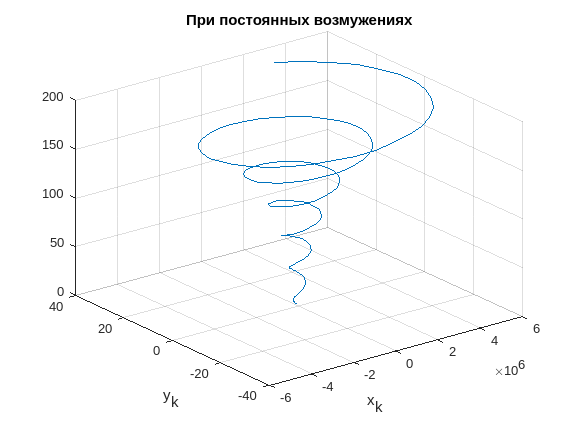

plot3(x_k_a(1,:), x_k_a(2,:),I);
title('При постоянных возмужениях');
xlabel('x_k');
ylabel('y_k');
grid on;

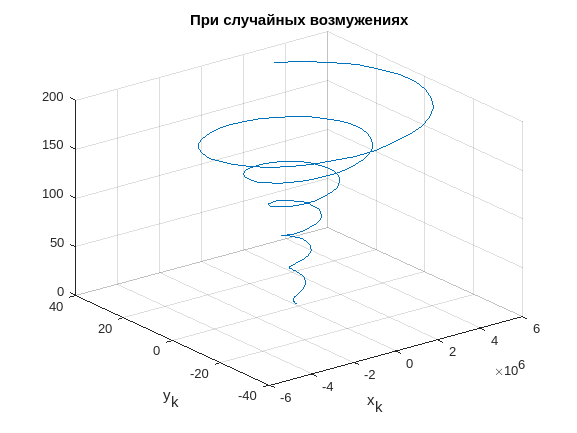

plot3(x_k_b(1,:), x_k_b(2,:),I);
title('При случайных возмужениях');
xlabel('x_k');
ylabel('y_k');
grid on;

**Лабораторная работа 2**

**Моделирование измерительной системы**

Цель работы: моделирование измерений и определение наблюдаемости вектора состояния системы.

Уравнение измерений:

$z_k ={\textrm{Hx}}_k +V_k$, $z_k -r$-вектор измерений, H - (rxn) - матрица измерений, V - r-вектор измерительного шума.

В нашей задаче $n=2,\;r=1\ldotp$

Воспользуемся критерием наблюдаемости Калмана:


$$S=\left\lbrack \begin{array}{c}
H\\
H*A
\end{array}\right\rbrack$$


r = 1;
H_a = [1 0];
H_b = [0 1];
S_a = [H_a; H_a*A];
rank(S_a) == n

ans = logical
   1


Система (а) наблюдаема.

S_b = [H_b; H_b*A];
rank(S_b) == n

ans = logical
   1


Система (б) наблюдаема.

Проведем моделирвоание уравнения:

z = ones(1,Sz);
X_ax = linspace(1,1000,1000);
for k = 1:Sz
   z(k) = mtimes(H_a,x_k_a(:,k)) + 50*randi([-1000,1000]);
end
plot(I, z);
hold on;
plot(I, x_k_a(1,:));
xlim([0 100]);
grid on;
legend('z_k','x_k');

**Лабораторная работа 3**

**Оценивание погрешностей навигационных систем**

Цель работы: оценить погрешности системы управления посредством ФК.

P = zeros(n,n, Sz);
P(:,:,1) = [10e4 0; 0 10e-8];
Q = [4 0; 0 10e-6];
R = 2500;
K = zeros(n,r,Sz);
K(:,:,1) = zeros(n,r);
Sz = 61;

Функция для фильтра Калмана в конце программы.

Примерним функцию:

x_kf4 = kalman_filter(z,P,Q,K,H_a,A,Sz,R,n);

Теперь построим графики:

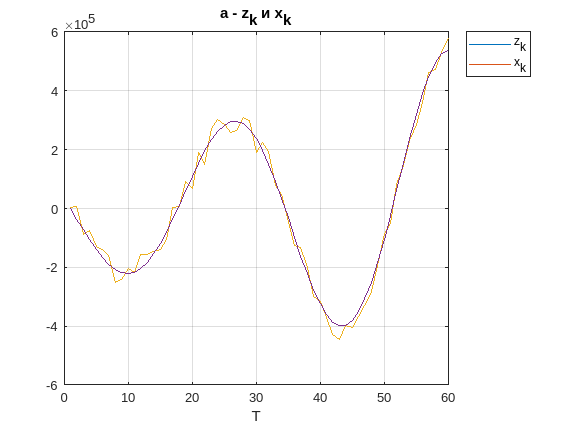

T = 0:60;
plot(I, z);
hold on;
plot(I, x_k_a(1,:));
xlim([0 60]);
grid on;
legend('z_k','x_k');
title('а - z_k и x_k');
xlabel('T');
hold off;

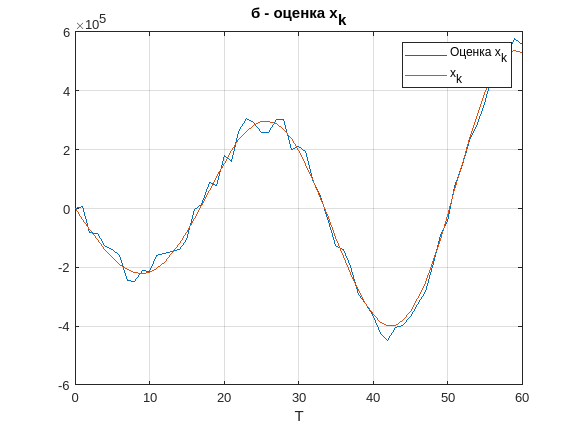

plot(T, x_kf4(1,1:61));
hold on;
plot(T, x_k_a(1,1:61));
grid on;
legend('Оценка x_k','x_k');
title('б - оценка x_k');
xlabel('T');
hold off;

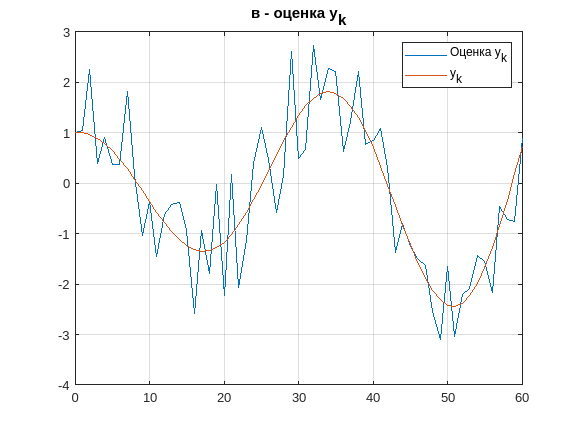

plot(T, x_kf4(2,1:61));
hold on;
plot(T, x_k_a(2,1:61));
grid on;
legend('Оценка y_k','y_k');
title('в - оценка y_k');
hold off;

**Лабораторная работа 4**

**Оценивание погрешностей навигационной системы в условиях стохастической неопределенности**

Цель работы: оценивание погрешностей ИНС посредством ФК в условиях отсутствия достоверной априорной информации о статистических характеристиках помех.

Вычислим оценку ветора состояния в различных случаях:

Случай а)

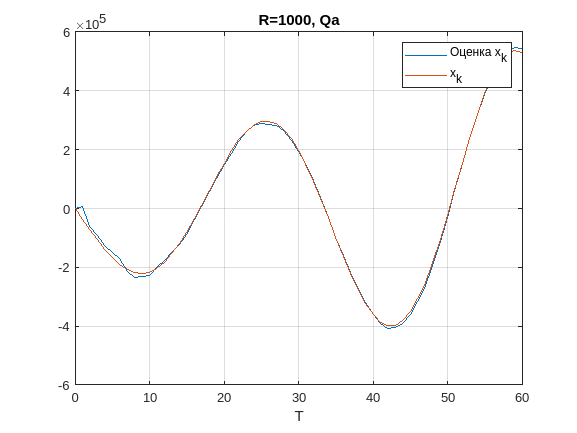

Q = [4 0; 0 10e-15];
R = 1000;
x_kf4 = kalman_filter(z,P,Q,K,H_a,A,Sz,R,n);
plot(T, x_kf4(1,1:61));
hold on;
plot(T, x_k_a(1,1:61));
grid on;
legend('Оценка x_k','x_k');
title('R=1000, Qa');
xlabel('T');
hold off;

Случай б)

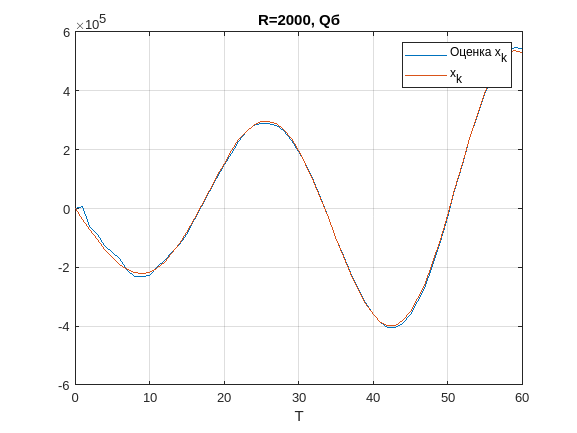

Q = [4 0; 0 10e-13];
R = 2000;
x_kf4 = kalman_filter(z,P,Q,K,H_a,A,Sz,R,n);
plot(T, x_kf4(1,1:61));
hold on;
plot(T, x_k_a(1,1:61));
grid on;
legend('Оценка x_k','x_k');
title('R=2000, Qб');
xlabel('T');
hold off;

Случай в)

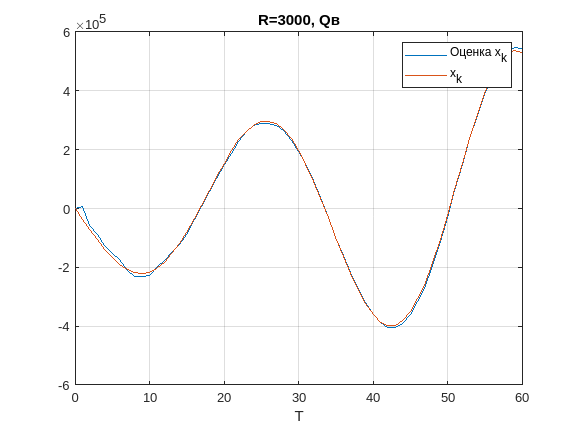

Q = [4 0; 0 10e-17];
R = 3000;
x_kf4 = kalman_filter(z,P,Q,K,H_a,A,Sz,R,n);
plot(T, x_kf4(1,1:61));
hold on;
plot(T, x_k_a(1,1:61));
grid on;
legend('Оценка x_k','x_k');
title('R=3000, Qв');
xlabel('T');
hold off;

Случай в)

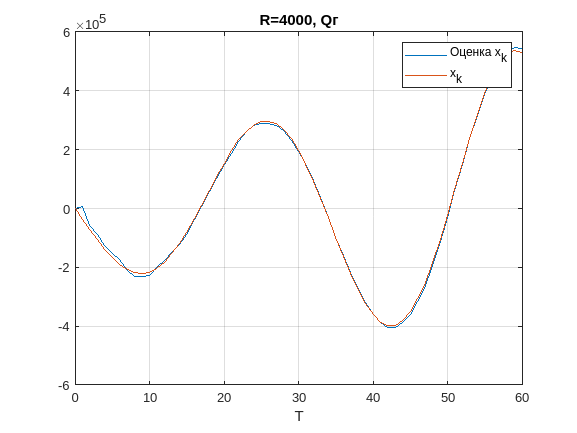

Q = [4 0; 0 10e-19];
R = 4000;
x_kf4 = kalman_filter(z,P,Q,K,H_a,A,Sz,R,n);
plot(T, x_kf4(1,1:61));
hold on;
plot(T, x_k_a(1,1:61));
grid on;
legend('Оценка x_k','x_k');
title('R=4000, Qг');
xlabel('T');
hold off;

Функция для фильтра Калмана:

function x_kalm = kalman_filter(z,P,Q,K,H,A,Sz,R,n)
x_kalm = ones(n,Sz);
    for k = 2:Sz
        P_kk = mtimes(mtimes(A,P(:,:,k-1)), transpose(A)) + Q;
        K(:,:,k) = mtimes(mtimes(P_kk, transpose(H)), inv(mtimes(mtimes(H,P_kk), transpose(H))+R));
        P(:,:,k) = mtimes((eye(n) - mtimes(K(:,:,k),H)), P_kk);
        x_kalm(:,k) = mtimes(A, x_kalm(:,k-1)) + mtimes(K(:,:,k), z(k) - mtimes(mtimes(H,A), x_kalm(:,k-1)));
    end
end